%bagfile入力
bag = rosbag("ros\robot.bag"); %bagfileのimport 
rosbag info ros\robot.bag      %bagfileのinfo

Path:     C:\Users\kodai\MATLAB\ros\robot.bag
Version:  2.0
Duration: 1:51s (111s)
Start:    11 15 2021 17:32:18.69 (1636965138.69)
End:      11 15 2021 17:34:10.5 (1636965250.05)
Size:     3.6 MB
Messages: 2375
Types:    diagnostic_msgs/DiagnosticArray       [60810da900de1dd6ddd437c3503511da]
          dynamic_reconfigure/Config            [958f16a05573709014982821e6822580]
          dynamic_reconfigure/ConfigDescription [757ce9d44ba8ddd801bb30bc456f946f]
          rosgraph_msgs/Log                     [acffd30cd6b6de30f120938c17c593fb]
          sensor_msgs/LaserScan                 [90c7ef2dc6895d81024acba2ac42f369]
          sensor_msgs/PointCloud2               [1158d486dd51d683ce2f1be655c3c181]
          tf2_msgs/TFMessage                    [94810edda583a504dfda3829e70d7eec]
Topics:   /back_scan                                         6 msgs  : sensor_msgs/LaserScan                
          /diagnostics                                     111 msgs  : diagnostic_msgs/DiagnosticA

%/mergeグラフ
bSel = select(bag,'Topic','/scan'); 
msgStructs = readMessages(bSel,'DataFormat','struct');
mergexy = rosReadCartesian(msgStructs{1}) %XY変換

mergexy =     0.0001   -0.1820
    0.0065   -0.1829
    0.1572   -2.6714
    0.1727   -2.6704
    0.0129   -0.1825
    0.2049   -2.6842
    0.2214   -2.6939
    0.2385   -2.7095
    0.2560   -2.7270
    0.2731   -2.7384


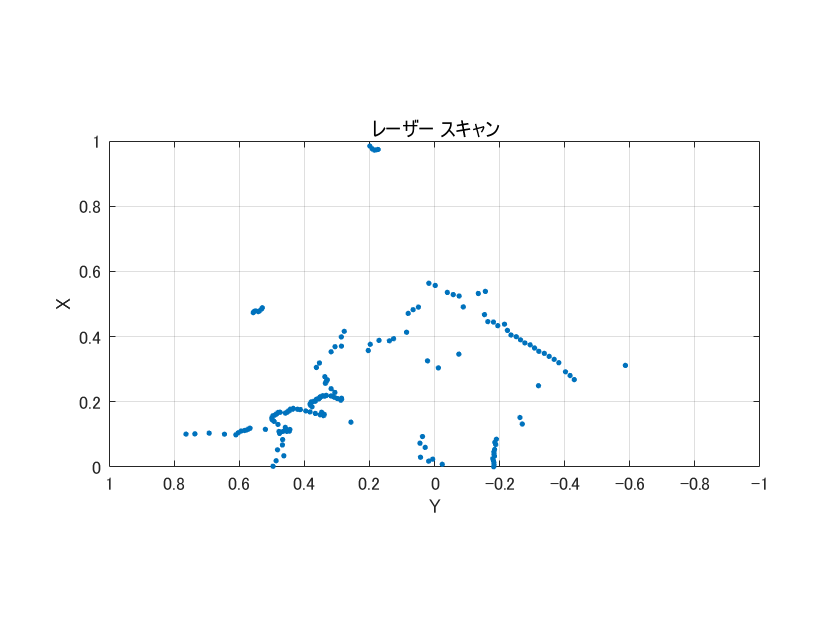

figure
rosPlot(msgStructs{1},'MaximumRange',1) %Plot(時間,"XY座標範囲",大きさ)
hold on

%/LRFグラフ
bSel = select(bag,'Topic','/front_scan'); 
msgStructs = readMessages(bSel,'DataFormat','struct');
LRFxy = rosReadCartesian(msgStructs{1}) %XY変換

LRFxy =    -0.1937   -0.3419
   -0.1916   -0.3431
   -0.1972   -0.3583
   -0.1950   -0.3595
   -0.1942   -0.3634
   -0.1929   -0.3663
   -0.1907   -0.3675
   -0.1889   -0.3695
   -0.1870   -0.3716
   -0.1848   -0.3727


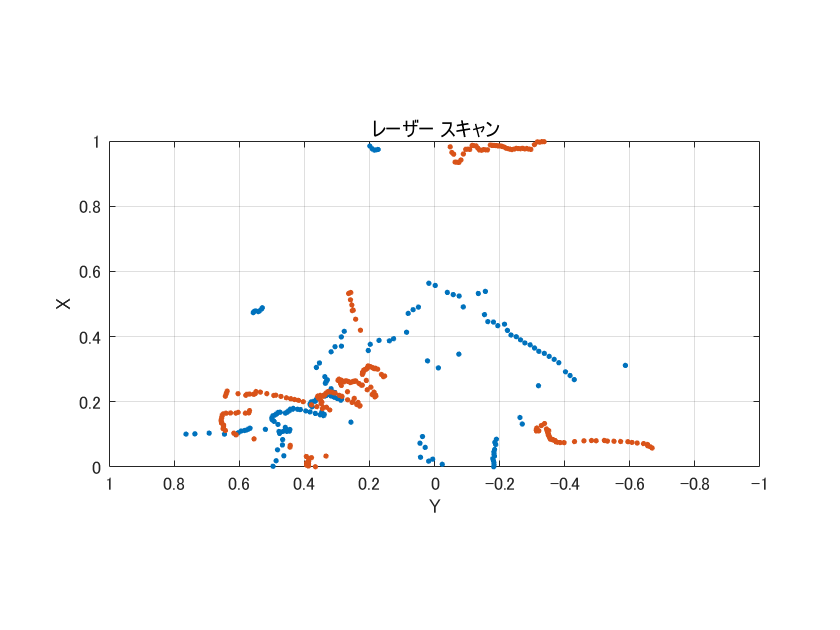

rosPlot(msgStructs{2},'MaximumRange',1) %Plot(時間,"XY座標範囲",大きさ)

%/ultrasonicscanerグラフ
bSel = select(bag,'Topic','/back_scan'); 
msgStructs = readMessages(bSel,'DataFormat','struct');
USSxy = rosReadCartesian(msgStructs{2}) %XY変換

USSxy =     0.0004    0.4920
    0.0411    1.1513
    0.0810    1.1451
    0.1199    1.1327
    0.1593    1.1278
    0.1988    1.1225
    0.2367    1.1100
    0.2763    1.1050
    0.3133    1.0899
    0.3527    1.0830


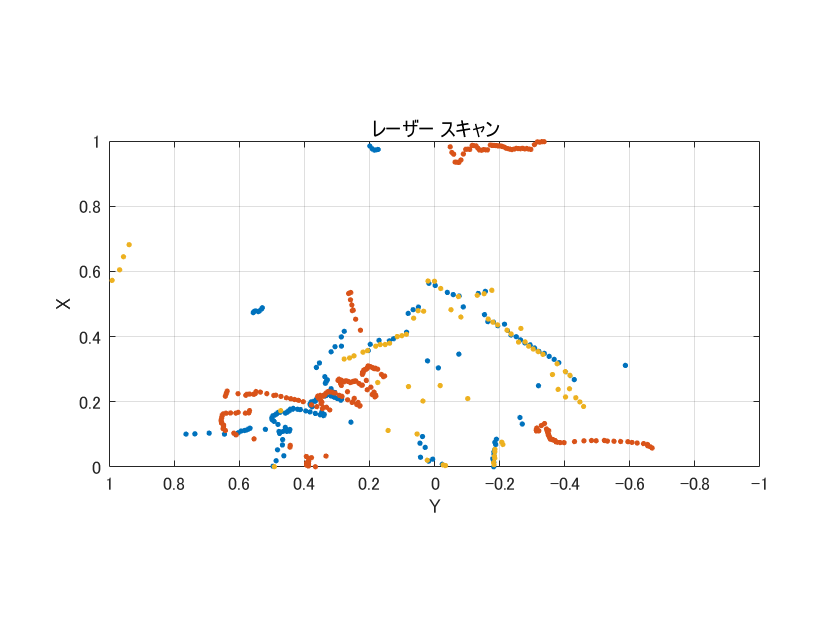

rosPlot(msgStructs{2},'MaximumRange',1) %Plot(時間,"XY座標範囲",大きさ)